## LSE analytical solution

load('EQ1_data.mat')
U = data(:,1);
Y = data(:,2);
N = numel(U);

Phi = [U, ones(N,1)];
x = (Phi'*Phi)\(Phi'*Y);

disp(x)

    9.7179
    3.1767



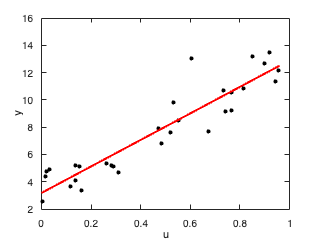

    6.2900
    4.8611



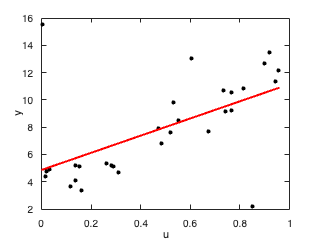


plot(U,Y,'k.',MarkerSize=12)
hold all
plot(U,[U,ones(N,1)]*x,'r',LineWidth=2)
ylabel('y')
xlabel('u')
ylim([2,16])

## Polynomial curve fitting

load('EQ2_data.mat')
U = data(:,1);
Y = data(:,2);
N = numel(U);

Phi = [ones(N,1), U, U.^2, U.^3];
x = (Phi'*Phi)\(Phi'*Y);
disp(x)

    2.6316
   10.8711
   -4.7890
   -2.3644



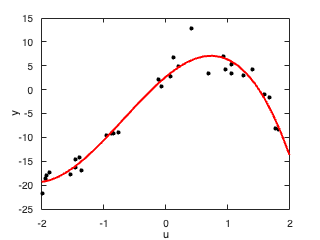


figure()
plot(U,Y,'k.',MarkerSize=12)
hold all
u = linspace(-2,2,N)';
plot(u, [ones(N,1), u, u.^2, u.^3]*x,'r',LineWidth=2)
ylabel('y')                            
xlabel('u')     
ylim([-25,15])


Phi = [ones(N,1), U, U.^2, U.^3, U.^4];
x = (Phi'*Phi)\(Phi'*Y);
disp(x)

    2.9236
   10.7278
   -5.4197
   -2.2903
    0.1788



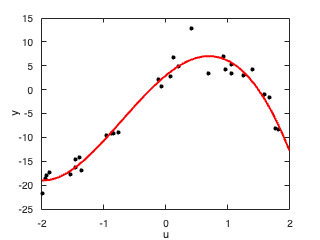


figure()
plot(U,Y,'k.',MarkerSize=12)
hold all
plot(u, [ones(N,1), u, u.^2, u.^3,u.^4]*x,'r',LineWidth=2)
ylabel('y')                            
xlabel('u')     
ylim([-25,15])

Phi = [ones(N,1), U, U.^2, U.^3, U.^4, U.^5, U.^6, U.^7,U.^8, U.^9,U.^10];
x = (Phi'*Phi)\(Phi'*Y);
disp(x)

    2.8512
   22.2041
   -8.0344
  -34.6432
    1.3158
   28.2023
    1.8142
   -9.5612
   -1.1077
    1.1038
    0.1607



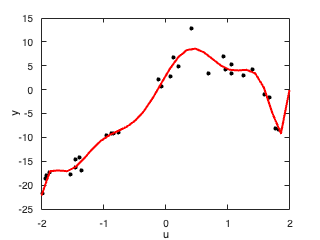


figure()
plot(U,Y,'k.',MarkerSize=12)

hold all
plot(u, [ones(N,1), u, u.^2, u.^3,u.^4,u.^5, u.^6,u.^7, u.^8,u.^9,u.^10]*x,'r',LineWidth=2)
ylabel('y')                            
xlabel('u')     
ylim([-25,15])

w = 1;
Phi = [ones(N,1), U, U.^2, U.^3, U.^4, U.^5, U.^6, U.^7,U.^8, U.^9,U.^10];
x = (Phi'*Phi + N*w*eye(11))\(Phi'*Y);
disp(x)

    0.2621
    1.5698
   -0.5542
    1.1978
   -0.6645
    0.8215
   -0.5202
   -0.0002
    0.2319
   -0.0942
   -0.0391



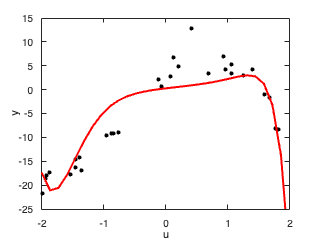


figure()
plot(U,Y,'k.',MarkerSize=12)

hold all
plot(u, [ones(N,1), u, u.^2, u.^3,u.^4,u.^5, u.^6,u.^7, u.^8,u.^9,u.^10]*x,'r',LineWidth=2)
ylabel('y')                            
xlabel('u')     
ylim([-25,15])

## Radial Basis Function Network fitting


eta = 5; % no. of neurons
C = -2:1:2;
w = 0;
for i = 1:eta
    R(:,i) = RB(U,C(i));
end
Phi = [ones(N,1), R];
x = (Phi'*Phi + N*w*eye(eta+1))\(Phi'*Y);
disp(x)

 -316.8202
  439.0018
 -457.8646
  689.2780
 -470.0494
  531.4965
 -220.5313
  327.6000
 -123.1868
  281.7783



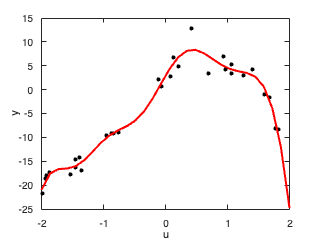


figure()
plot(U,Y,'k.',MarkerSize=12)
hold all
u = linspace(-2,2,N)';
for i = 1:eta
    R_pred(:,i) = RB(u,C(i));
end
plot(u, [ones(N,1), R_pred]*x,'r',LineWidth=2)
ylabel('y')                            
xlabel('u')     
ylim([-25,15])

function r = RB(u,u0)
r = exp(-(u-u0).*(u-u0));
end